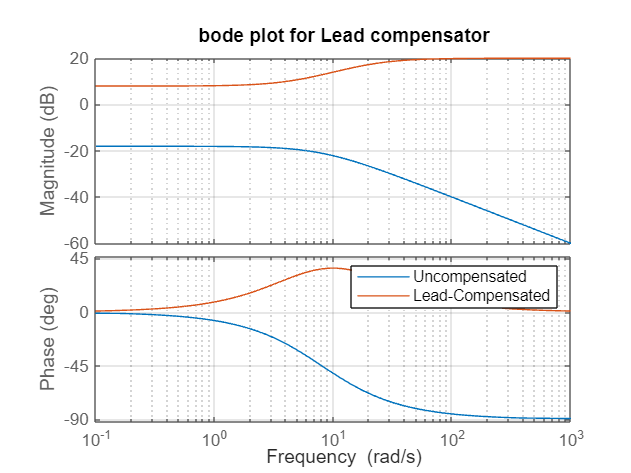

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT

s = tf('s');%%Define s as a transfer function variable in the Laplace domain
G1 = 1/(s + 8);%%The 1st order system transfer function
C_lead = 10*(s + 5)/(s + 20);%%lead compensator
C_lag = (s + 4)/(s + 0.4);%%lag compensator
C_total= G1*C_lead*C_lag;%%final compensated system
C_L=feedback(C_total,1);%%%the closed loop for the cascaded 
%%C_lead bode plots
figure;
bode(G1, C_lead);
grid on;
title('bode plot for Lead compensator')
legend('Uncompensated', 'Lead-Compensated')

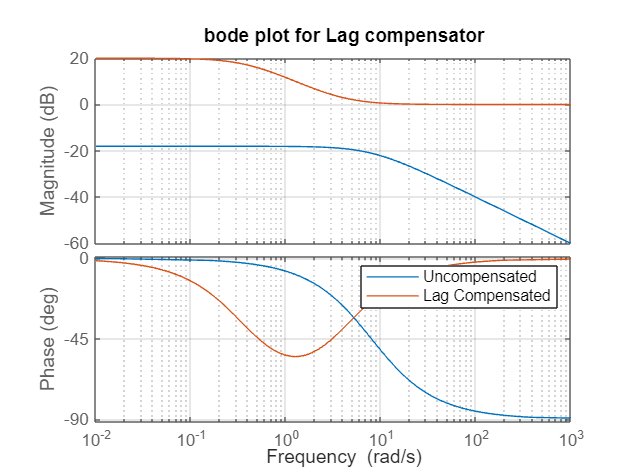

%%C-lag bode plot
figure;
bode(G1, C_lag);
grid on;
title('bode plot for Lag compensator')
legend('Uncompensated', 'Lag Compensated')

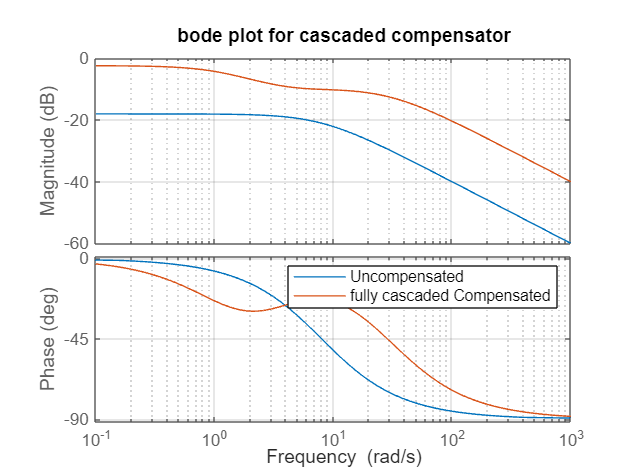

%%bode plot for cascaded ssytem
figure;
bode(G1,C_L);
grid on;
title('bode plot for cascaded compensator')
legend('Uncompensated', 'Compensated')

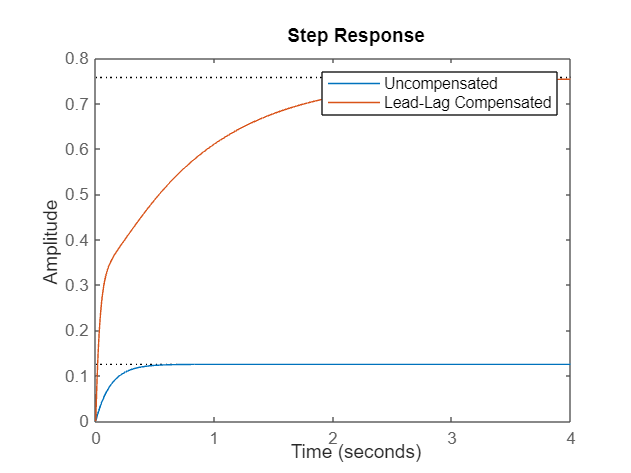

%%plotting the step response
step(G1, C_L);
legend('Uncompensated', 'Lead-Lag Compensated')